# Part 7: Demonstration

## Exercise 7.1: Navigating a 3D maze

For this exercise we first get the route:

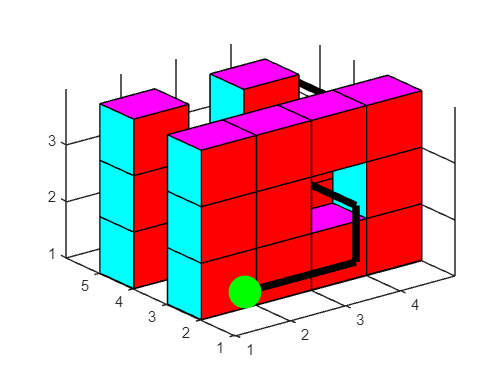

clc; clear all; close all;
run("maze/exercise_4_files/map_script_3d.m"); % Either need route or route scaled

which defines the route variable. Then we scale it according to the relative map size in the real track:

%% Scale the route
x_scale = 0.61;
y_scale = 0.535;
z_scale = 0.725;

x_offset = 0.3;
y_offset = 0.5;
z_offset = 0.25;

% Make a copy of the route
route_scaled = route;

% Scale the copy
route_scaled(:,1) = (route_scaled(:,1) - 1) * x_scale + x_offset;
route_scaled(:,2) = (route_scaled(:,2) - 1) * y_scale + y_offset;
route_scaled(:,3) = (route_scaled(:,3) - 1) * z_scale + z_offset;

% Print the scaled route
route_scaled

route_scaled =     0.3000    0.5000    0.2500
    0.9100    0.5000    0.2500
    1.5200    0.5000    0.2500
    1.5200    0.5000    0.9750
    1.5200    1.0350    0.9750
    1.5200    1.5700    0.9750
    1.5200    1.5700    1.7000
    2.1300    1.5700    1.7000
    2.1300    2.1050    1.7000
    2.1300    2.6400    1.7000


At last, we initalize the parameters that must be defined for the simulation to work:

wall_color = [0.8 0.2 0.2];
sample_time = 4e-2;
publish_rate = 1 * sample_time;
x0 = 36;
y0 = 80;
z0 = 1;
g = 9.80665;
mass_drone = 0.32 ;
mass_rod = 0.0;
mass_tip = 0;
mass_total = mass_drone + mass_rod + mass_tip;
stiffness_rod = 100 ;
critical_damping_rod = 2 * sqrt(mass_total * stiffness_rod) ;
stiffness_wall = 100 ;
critical_damping_wall = 2 * sqrt(mass_total * stiffness_wall) ;
inertia_xx = 0.007 ;
inertia_yy = 0.007 ;
inertia_zz = 0.012 ;
arm_length = 0.17 ;
rotor_offset_top = 0.01 ;
motor_constant = 8.54858e-06 ;
moment_constant = 0.016 ;
max_rot_velocity = 838 ;
allocation_matrix = ...
    [1 1 1 1
     0 arm_length 0 -arm_length
     -arm_length 0 arm_length 0
     -moment_constant moment_constant -moment_constant moment_constant] ;
mix_matrix = inv(motor_constant * allocation_matrix) ;
air_density = 1.2041;
drag_coefficient = 0.47;
reference_area = pi * 75e-3^2;

We the run the simulation file *'uas_main_exe_7_1.slx*' and watch the drone fly.

## Exercise 7.2: Poting the position controller to the real system

### Exercise 7.2.1: Finding the relation between PWN and vertical accelleration

For this task we first need to find the relation between PWN thrust values and the vertical accelleration which can be done through linear fitting. 

We use the uas_main_exe_7_2.slx model as this has been reprogrammed tol the joystick. Use the following parameters:

clc; clear all; close all;

run("environment_variables.m");

#### Plotting the data

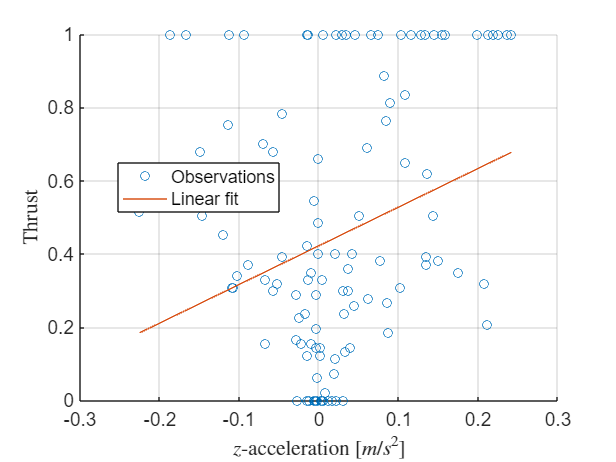

load("data/thrust_relation.mat")
start = 21;
imu = out.Acc_Z{2}.Values.Data(start:floor(end/2))-g;
pwm = out.Acc_Z{1}.Values.Data(start:floor(end/2));
xy = [imu,pwm];
xy = rmoutliers(xy);

% We should remove negative thrust values?
xy = xy(find(xy(:,2)>=0), :);

figure(1)
scatter(xy(:,1), xy(:,2))
P = polyfit(xy(:,1), xy(:,2), 1);
yfit = P(1)*xy(:,1) + P(2);
hold on
plot(xy(:,1),yfit)
grid on
hold off
xlabel('$z$-acceleration $[m/s^2]$','Interpreter','Latex')
ylabel('Thrust','Interpreter','Latex')
legend('Observations', 'Linear fit', Location='best')
savepdf(gcf, 'images/thrust_relation')

### Exercise 7.2.2: Adjusting the controller

For our controller, we decided to use a PID controller as this has yielded the best results in practice. 

pos_kp = 0.4;
pos_ki = 0.002;
pos_kd = 0.3;
vel_kp = 0;

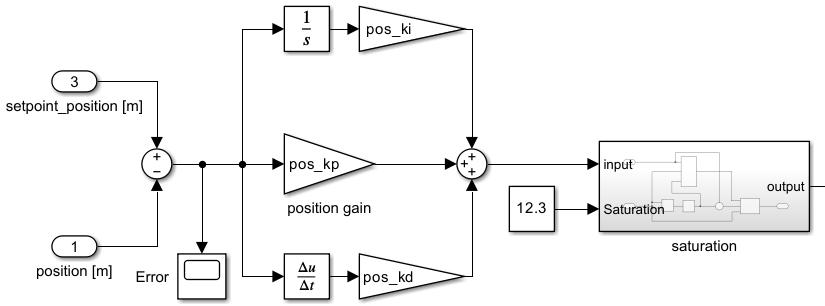

%% Relation between thrust and vertical acceleration
%pos_ki = 0.000033;
%vel_kp = 0.25;
PWM = 60000;
P = [1.3999, 0.2601] * PWM;

% Make route
[coords Start_position] = fetch_hoops(true);
if Start_position == false
    Start_position = transpose([1.8 -4.45 0]);% transpose([1.82 -5.73 0])
end
route = [0 0 1;
    1 0 1];
route(1,:) = route(1,:) + Start_position';
route(2,:) = route(2,:) + Start_position';

Handy commands

% roslaunch vrpn_client_ros sample.launch server:=192.168.1.129
% cfstart #

## Original controller

pos_kp = 4;
pos_ki = 0.01;
pos_kd = 0;

vel_kp = 2.2;

Saturation = 12.3;
angle_saturation = 10; % Ensuring it doesn't make to rapid moves

mass_drone = 0.68;

Relation between thrust and vertical acceleration

%pos_ki = 0.000033;
%vel_kp = 0.25;
PWM = 60000;
P = [1.3999, 0.2601] * PWM;

Make route

[coords Start_position] = fetch_hoops(true);
if Start_position == false
    Start_position = transpose([1.8 -4.45 0]);% transpose([1.82 -5.73 0])
end
route = [0 0 1;
    1 0 1];
route(1,:) = route(1,:) + Start_position';
route(2,:) = route(2,:) + Start_position';

Handy commands

% roslaunch vrpn_client_ros sample.launch server:=192.168.1.129
% cfstart #

#### Exercise 7.2.2: Hovering 

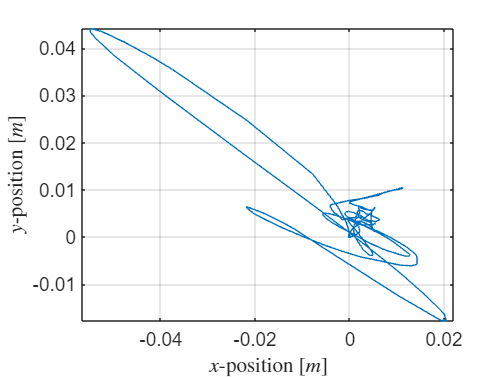

run1 = load("data/Run_7_2_part1_fin.mat");
offset = run1.out.Position.signals.values(1,:);
% Start pos 7.2.2
%     2.2661
%    -5.0191
%     0.0336

x = run1.out.Position.signals.values(:,1)-offset(1);
y = run1.out.Position.signals.values(:,2)-offset(2);
z = run1.out.Position.signals.values(:,3);
time = run1.out.Position.time;

figure
plot(x,y)
axis 'equal'
xlabel('$x$-position $[m]$','Interpreter','Latex')
ylabel('$y$-position $[m]$', 'Interpreter','Latex')
grid on
savepdf(gcf, 'images/exe7_2_hover_xy')


figure
plot(time, [x+1,y+1,z]) % The +1 is just a formality
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Position $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Interpreter','Latex', 'Location', 'best')
grid on
savepdf(gcf, 'images/exe7_2_hover_xyz')


figure
plot(time, squeeze(run1.out.Error.signals.values))
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Error $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Interpreter','Latex', 'Location', 'best')
grid on
savepdf(gcf, 'images/exe7_2_hover_error')

#### Exercise 7.2.2: Flying between two coordinates

% Route used
go_to_position = [2.85;-5.69; 0];

% Make route
route = [0 0 1;
    1 0 1];
route(1,:) = route(1,:) + go_to_position';
route(2,:) = route(2,:) + go_to_position';

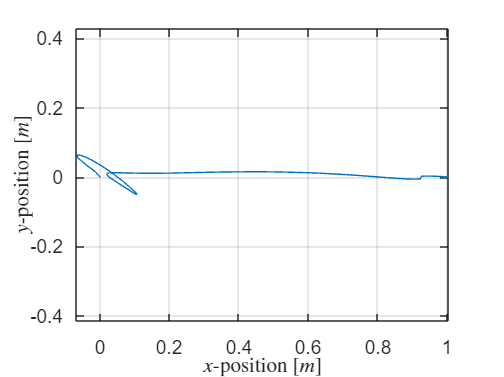

run2 = load("data/Run_7_2_part2_fin.mat");
offset = run.out.Position.signals.values(1,:);

x = run2.out.Position.signals.values(:,1)-offset(1);
y = run2.out.Position.signals.values(:,2)-offset(2);
z = run2.out.Position.signals.values(:,3);
time = run2.out.Position.time;

figure(1)
plot(x,y)
axis 'equal'
xlabel('$x$-position $[m]$','Interpreter','Latex')
ylabel('$y$-position $[m]$', 'Interpreter','Latex')
grid on
savepdf(gcf, 'images/exe7_2_moving_xy')

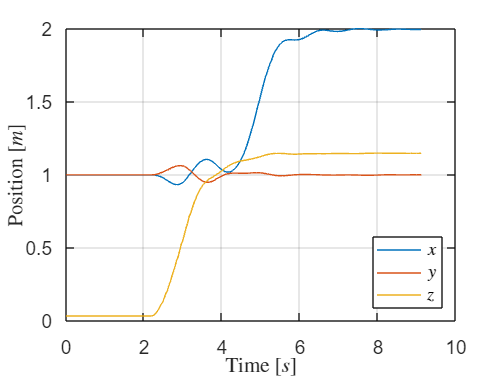


figure(2)
plot(time, [x+1,y+1,z]) % The +1 is just a formality
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Position $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Interpreter','Latex', 'Location', 'best')
grid on
savepdf(gcf, 'images/exe7_2_moving_xyz')

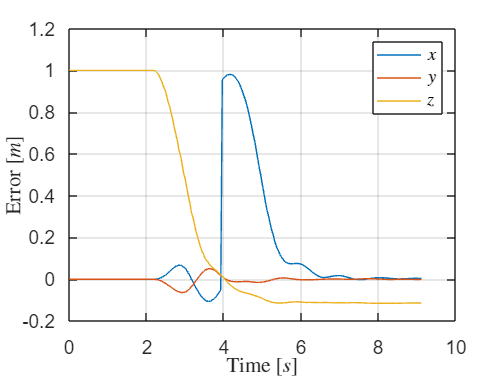


figure(3)
plot(time, squeeze(ru2n.out.Error.signals.values))
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Error $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Interpreter','Latex', 'Location', 'best')
grid on
savepdf(gcf, 'images/exe7_2_moving_error')

## Exercise 7.3: Trajectory planning

#### Environment Parameters

clc; clear all; close all; clf;

run("environment_variables.m");

%Controller
pos_kp = 0.4;
pos_ki = 0.002;
pos_kd = 0.3;
vel_kp = 0;

% Linear relation
PWM = 60000;
P = [1.3999, 0.2601] * PWM;

% Ensuring it doesn't make to rapid moves
angle_saturation = 10;

#### Trajectory Planning

[coords start_pos] = fetch_hoops(true);
tot_time = 60;
knots = [0 tot_time];
waypoints = cell(1,2);
if start_pos == false
    start_pos = load("data/7_3_start_pos.mat");% transpose([1.82 -5.73 0])
    start_pos = cell2mat(struct2cell(start_pos));
end
waypoints{1} = [0;0;0];
waypoints{2} = [0;0;0];
box_sizes = [0.1 0.04 0.06]; % Waypoints, center, ends
box_dist = 0.5;
order = 13;

% Reearange coordinates to the wanted
coord4 = coords(1,:);
coord3 = coords(2,:);
coord2 = coords(3,:);
coord1 = coords(4,:);

coord1(1:3) = coord1(1:3)-start_pos';
coord2(1:3) = coord2(1:3)-start_pos';
coord3(1:3) = coord3(1:3)-start_pos';
coord4(1:3) = coord4(1:3)-start_pos';

% Get the corridors
corridors = pos_2_corridors(waypoints{1}', waypoints{2}', coord1, coord2, coord3, coord4, box_sizes, box_dist, tot_time, false);
make_plots = false;

% Get the polynomial trajectory
poly_traj = uas_minimum_snap(knots, order, waypoints, corridors, make_plots);

Optimization will be performed on end derivatives. This will improve optimization performance.
solving 1 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 2 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 3 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
Done!
Elapsed time is 0.344479 seconds.


### 7.3 Plot

poly_traj_path = 'C:\Users\jonas\AppData\Roaming\MathWorks\MATLAB Add-Ons\Collections\traj_gen-matlab';
addpath([poly_traj_path '\sub_utils']) % for drawing cube             

run3 = load("data/Run_7_3_good_run.mat");
offset = run3.out.Position.signals.values(1,:);
line_colors = {'#0072BD', '#D95319', '#EDB120'};

bad_reading = 1212;
run3.out.Position.signals.values(bad_reading,:) = [];
run3.out.Error.signals.values(:, :, bad_reading) = [];
x = run3.out.Position.signals.values(:,1)-offset(1);
y = run3.out.Position.signals.values(:,2)-offset(2);
z = run3.out.Position.signals.values(:,3);
time = run3.out.Position.time;
display(time(bad_reading))

   48.4400



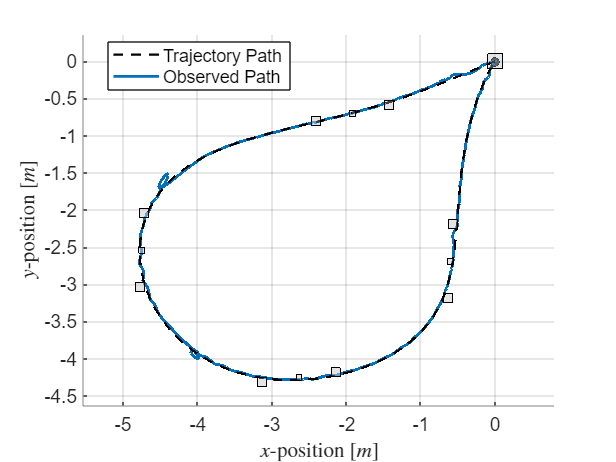

time(bad_reading) = [];
obj = poly_traj;

figure(1)
hold on
for pin = obj.pinSet % per pin
    if pin.d == 0                    
        X = pin.X; 
        if size(X,2) == 1  % FixPin
            if obj.dim == 2 % 2D
                plot(X(1),X(2),'ko','MarkerFaceColor',[0.2 0.2 0.2]);                                
                xlabel('$x$','Interpreter','latex') ;ylabel('$y$','Interpreter','latex'); 
            else   % 3D          
                plot3(X(1),X(2),X(3),'ko','MarkerFaceColor',[0.2 0.2 0.2]);     
                xlabel('$x$','Interpreter','latex') ;ylabel('$y$','Interpreter','latex'); zlabel('z','Interpreter','latex');                                
            end
        else % LoosePin
            if obj.dim == 2 % 2D
                rectangle('Position',[X(1,1) X(2,1) X(1,2)-X(1,1) X(2,2)-X(2,1)],'FaceColor',[0.8 .8 .8],'EdgeColor','k','LineWidth',1)         
                xlabel('$x$','Interpreter','latex') ;ylabel('$y$','Interpreter','latex');                                 
            else % 3D
                draw_box(X(:,1),X(:,2),[0.8 .8 .8],0.3)
                xlabel('$x$','Interpreter','latex') ;ylabel('$y$','Interpreter','latex'); zlabel('z','Interpreter','latex');                                
            end
        end
    end      
end
Nplot = 100;
ts = linspace(obj.Ts(1),obj.Ts(end),Nplot);
Xs = obj.eval(ts,0);
qw{1} = plot3(Xs(1,:),Xs(2,:),Xs(3,:),'k--', 'LineWidth',1.5);                   
qw{2} = plot(x,y, 'LineStyle','-', 'Color','#0072BD', 'LineWidth',2);
axis 'equal'
xlabel('$x$-position $[m]$','Interpreter','Latex')
ylabel('$y$-position $[m]$', 'Interpreter','Latex')
grid on
legend([qw{:}], {'Trajectory Path','Observed Path'}, 'location', 'best')
savepdf(gcf, 'images/exe7_3_moving_xy')
hold off

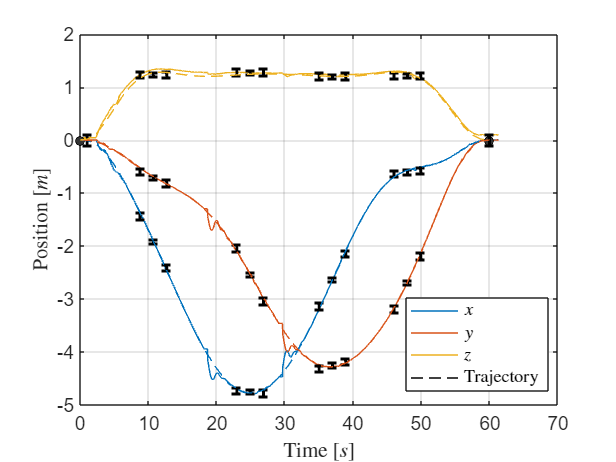


clf;
figure(2)
plot(time, [x,y,z]) % The +1 is just a formality
hold on
plot(NaN,NaN,'k--');
plotOrder = 1;
for dd = 1:obj.dim          
    % 1. Draw pin first 
    for pin = obj.pinSet % per pin
        t = pin.t; d = pin.d; X = pin.X;                                             
        if size(X,2) == 2   % LoosePin 
            errorbar(t,(X(dd,1)+X(dd,2))/2,(X(dd,2)-X(dd,1))/2,'k-','LineWidth',2); 
        else % FixPin
            plot(t,X(dd),'ko','MarkerFaceColor',[0.2 0.2 0.2]);
        end                              
    end                    
end

Nplot = 50;
ts = linspace(obj.Ts(1),obj.Ts(end),Nplot);
Xs = obj.eval(ts,d);
for dd = 1:obj.dim                     
    hold on
    plot(ts,Xs(dd,:),'LineStyle','--', 'Color', string(line_colors(dd)))
end

xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Position $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Trajectory', 'Interpreter','Latex', 'Location', 'best')
grid on
savepdf(gcf, 'images/exe7_3_moving_xyz')
hold off

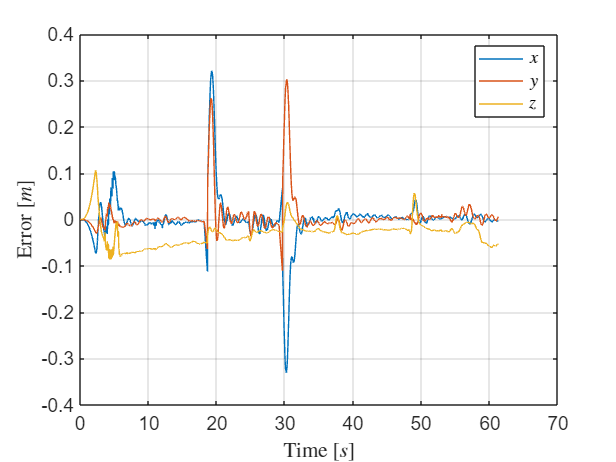


figure(3)
plot(time, squeeze(run3.out.Error.signals.values))
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Error $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Interpreter','Latex', 'Location', 'best')
grid on
savepdf(gcf, 'images/exe7_3_moving_error')

## Functions

function savepdf(figure, name)
    fontsize(figure, scale=1.3)
    set(figure,'Units','Inches');
    pos = get(figure,'Position');
    set(figure,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])
    print(figure, name,'-dpdf','-r0')
end

#### Fetch hoops

function [coords drone] = fetch_hoops(preload)
    if preload == false
        setup = sim('simulink/fetch_coords.slx');
        coord1 = setup.hoop1.Data(end,:);
        coord2 = setup.hoop2.Data(end,:);
        coord3 = setup.hoop3.Data(end,:);
        coord4 = setup.hoop4.Data(end,:);
        coords = [coord1; coord2; coord3; coord4];
        drone = setup.drone_start.Data(end, :)';
    else
        %save('hoops.mat', 'coords');
        coords = load('data/hoops_flyday.mat');
        coords = coords.coords;
        drone = false;
    end

end